# DATA 4: PHYLOGENTIC TREE

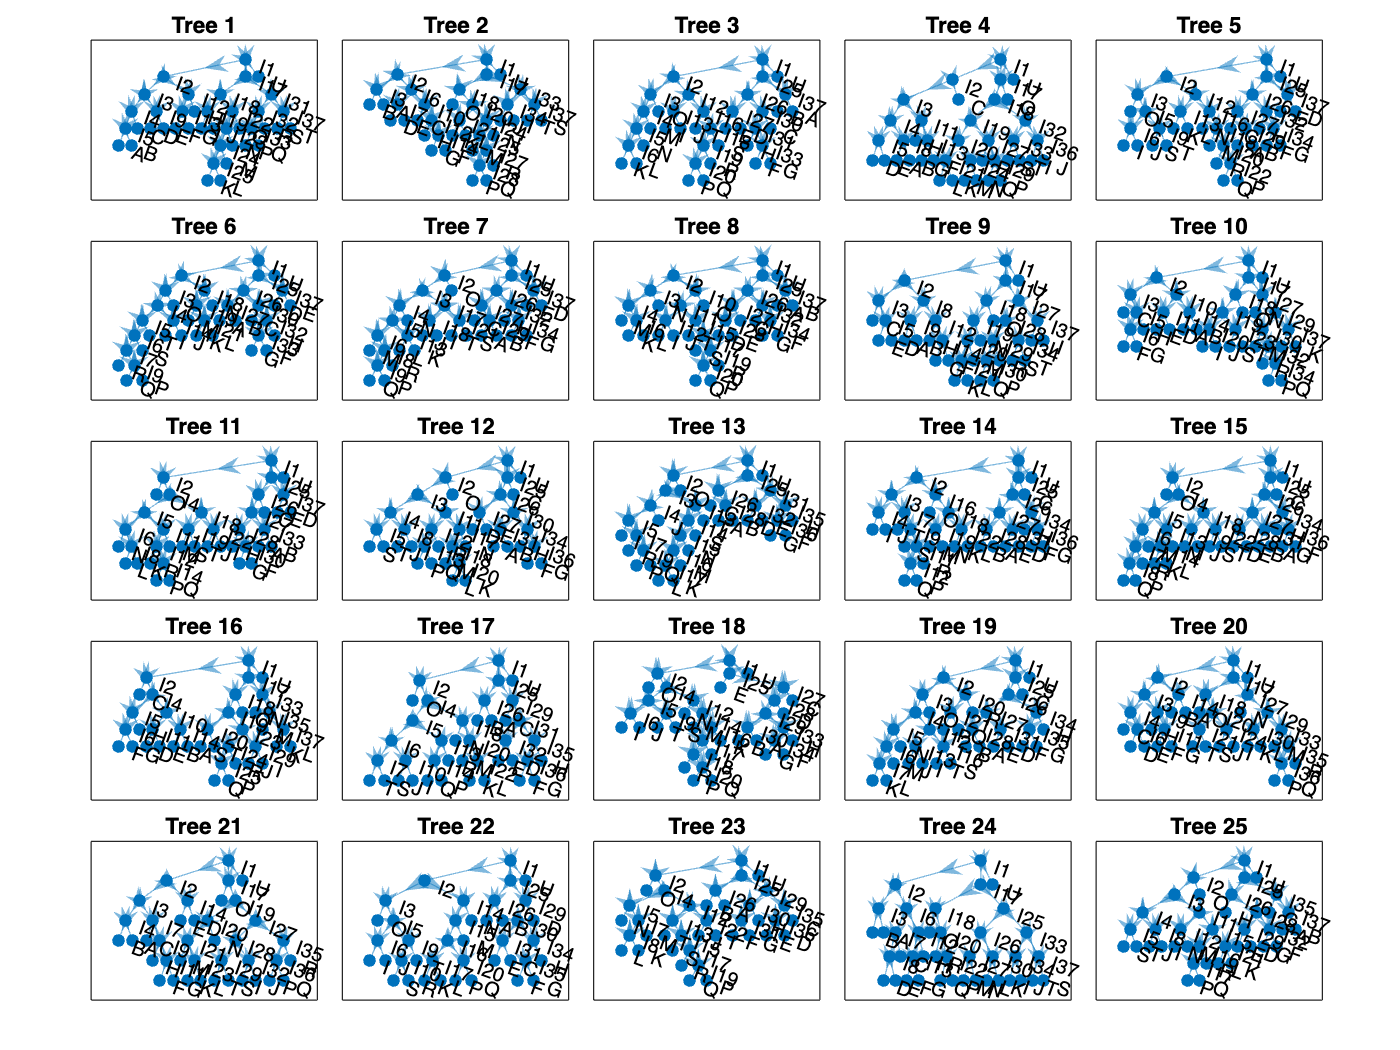

% (C) 2026 Moo K. Chung
% University of Wisconsin
%
% Data came from Prof. Cecile Ane from the Department of Statistis,
% University of Wisconsin-Madison based on publication 
% @article{rose.2025,
%   title={Phylogenomics of the tetraploid Hawaiian lobeliads: Implications for their origin, dispersal history, and adaptive radiation},
%   author={Rose, Jeffrey P and Li, Bing and Sporck-Koehler, Margaret J and Stacy, Elizabeth A and Wood, Kenneth R and Lemmon, Emily Moriarty and Lemmon, Alan R and An{\'e}, C{\'e}cile and Sytsma, Kenneth J and Givnish, Thomas J},
%   journal={Proceedings of the National Academy of Sciences},
%   volume={122},
%   pages={e2421004122},
%   year={2025},
% }
% If you are using data here, please reference this paper. 

%Simulated phylogenetic tree mainly used for testing algoirthms and bebugging
trees = read_and_display_newick('multitrees.newick');

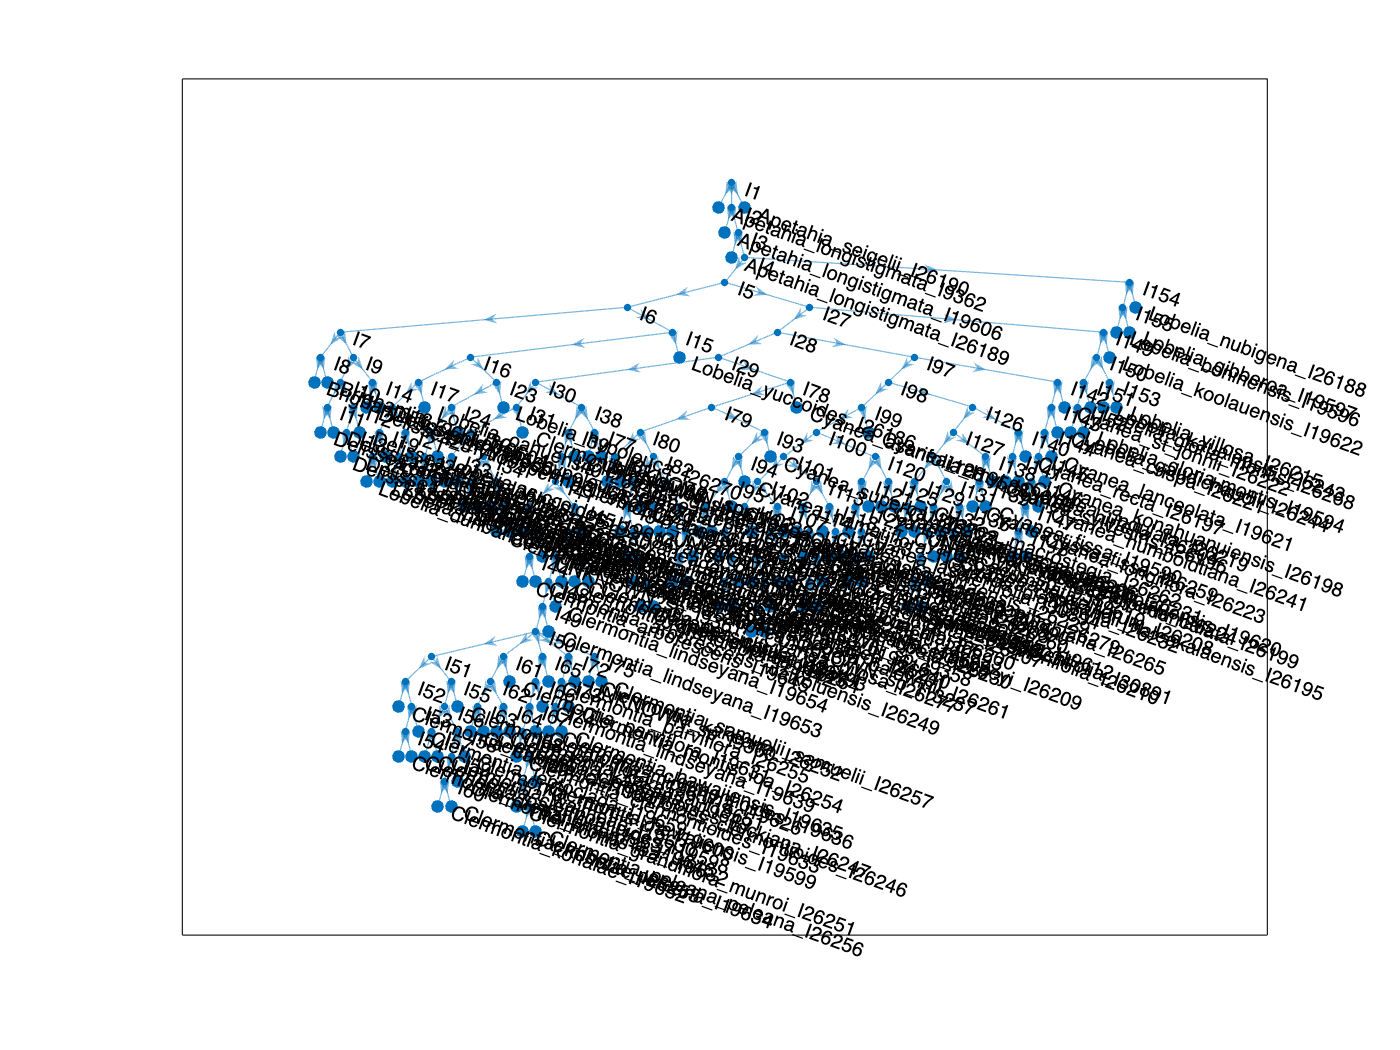

% The folder nuclear.genetrees.final.zip contains 634 gene trees, one per nuclear locus. Each tree represents the 
% inferred ancestral relationships among copies of a single gene across the sampled individuals, encoding
% relative ancestry structure for that locus rather than a species-level evolutionary history.
% 
% These trees are inferred independently from aligned DNA sequences using a probabilistic substitution model and summarize 
% uncertainty via bootstrap consensus (.contree). The trees encode relative time rather than absolute calendar 
% time, specifying the ordering of ancestral events (what occurs earlier or later).
%
G = phylogenetic_contree_read('L2.0.fasta.contree');
plylogenic_contree_display(G);

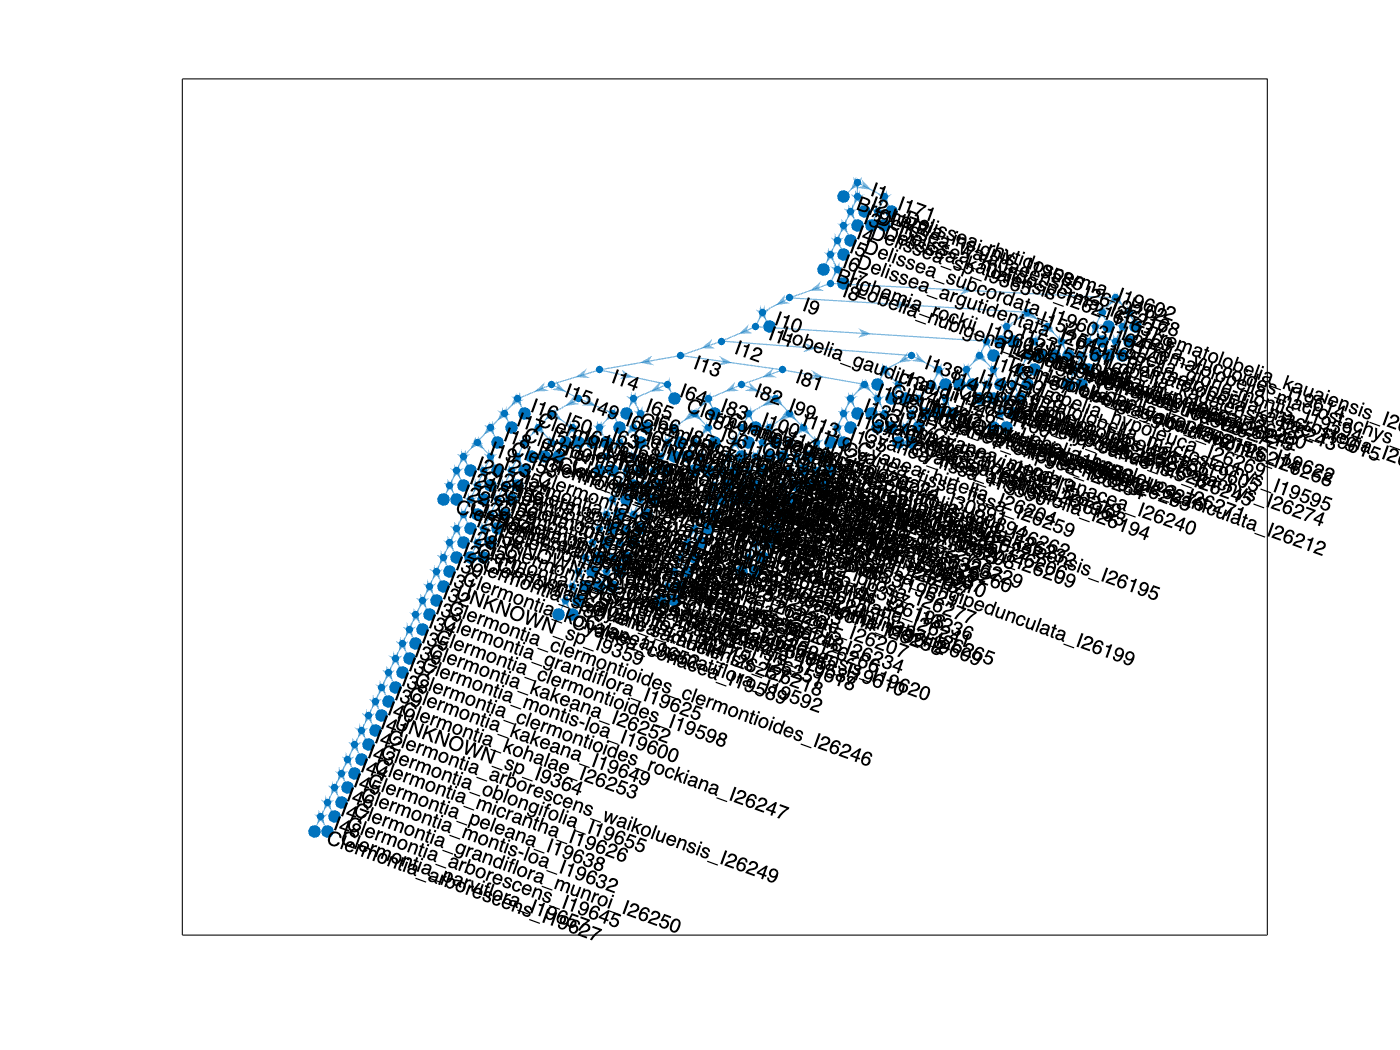


P = phylogenetic_contree_read('L387.0.fasta.contree');
plylogenic_contree_display(P);

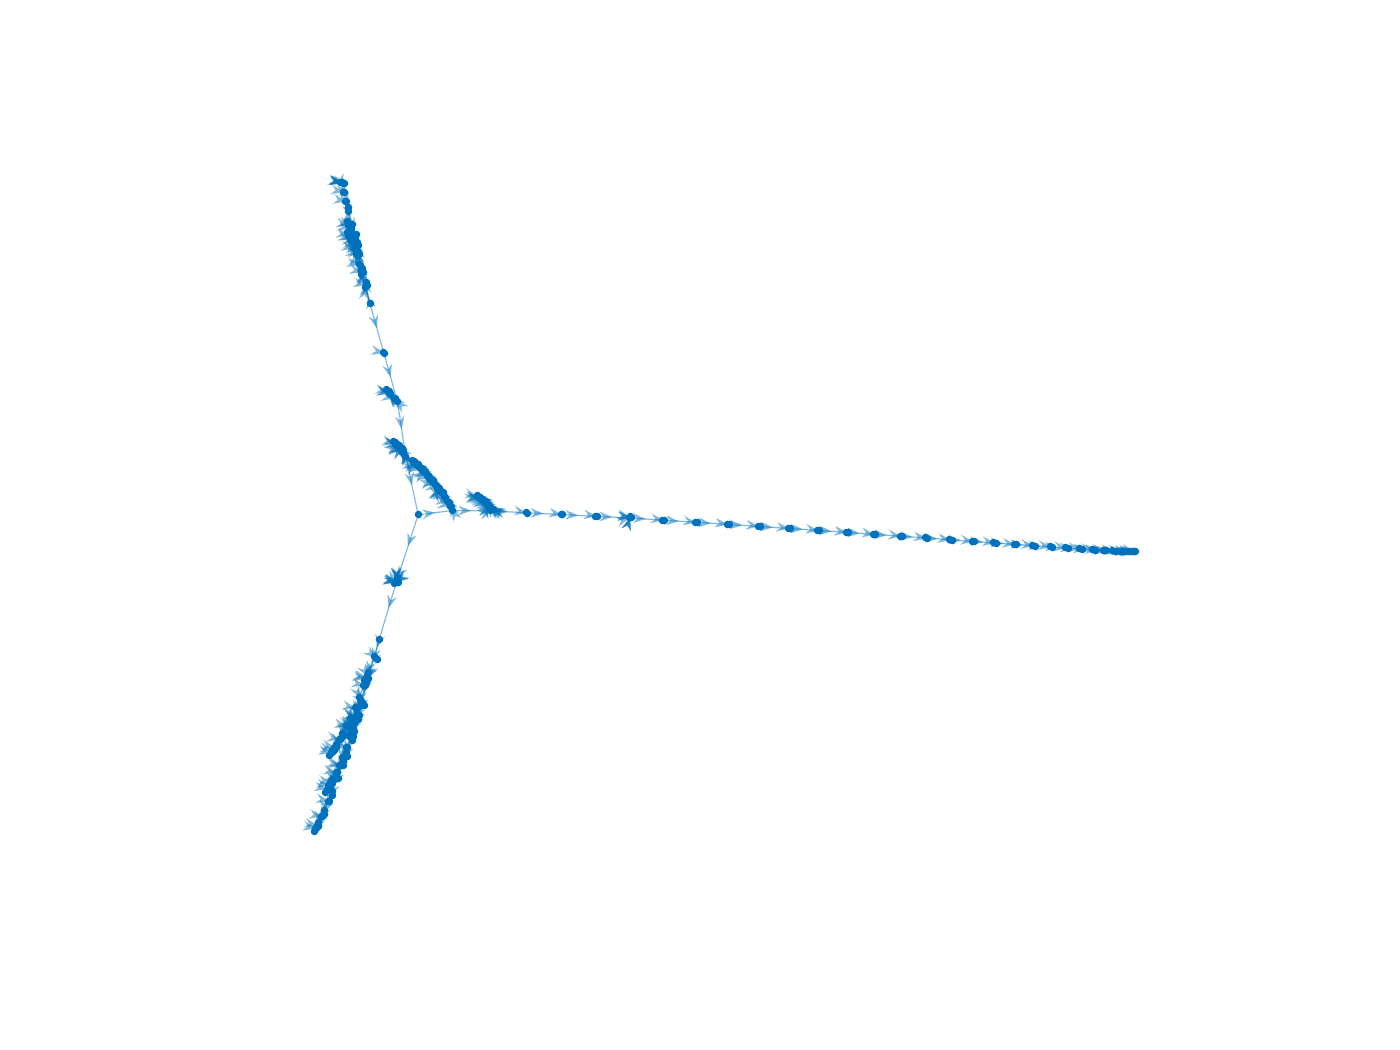

% The original gene trees contain extensive biological information. We focus exclusively on the mathematical and statistical
% properties of the underlying tree structures. To this end, we strip all biological annotations and represent each 
% tree as a directed graph in MATLAB, corresponding to the 1-dimensional simplicial complex (its 1-skeleton) underlying the tree topology.

G=phylogenetic2graph(P);
figure('Color','w'); plot(G); axis off

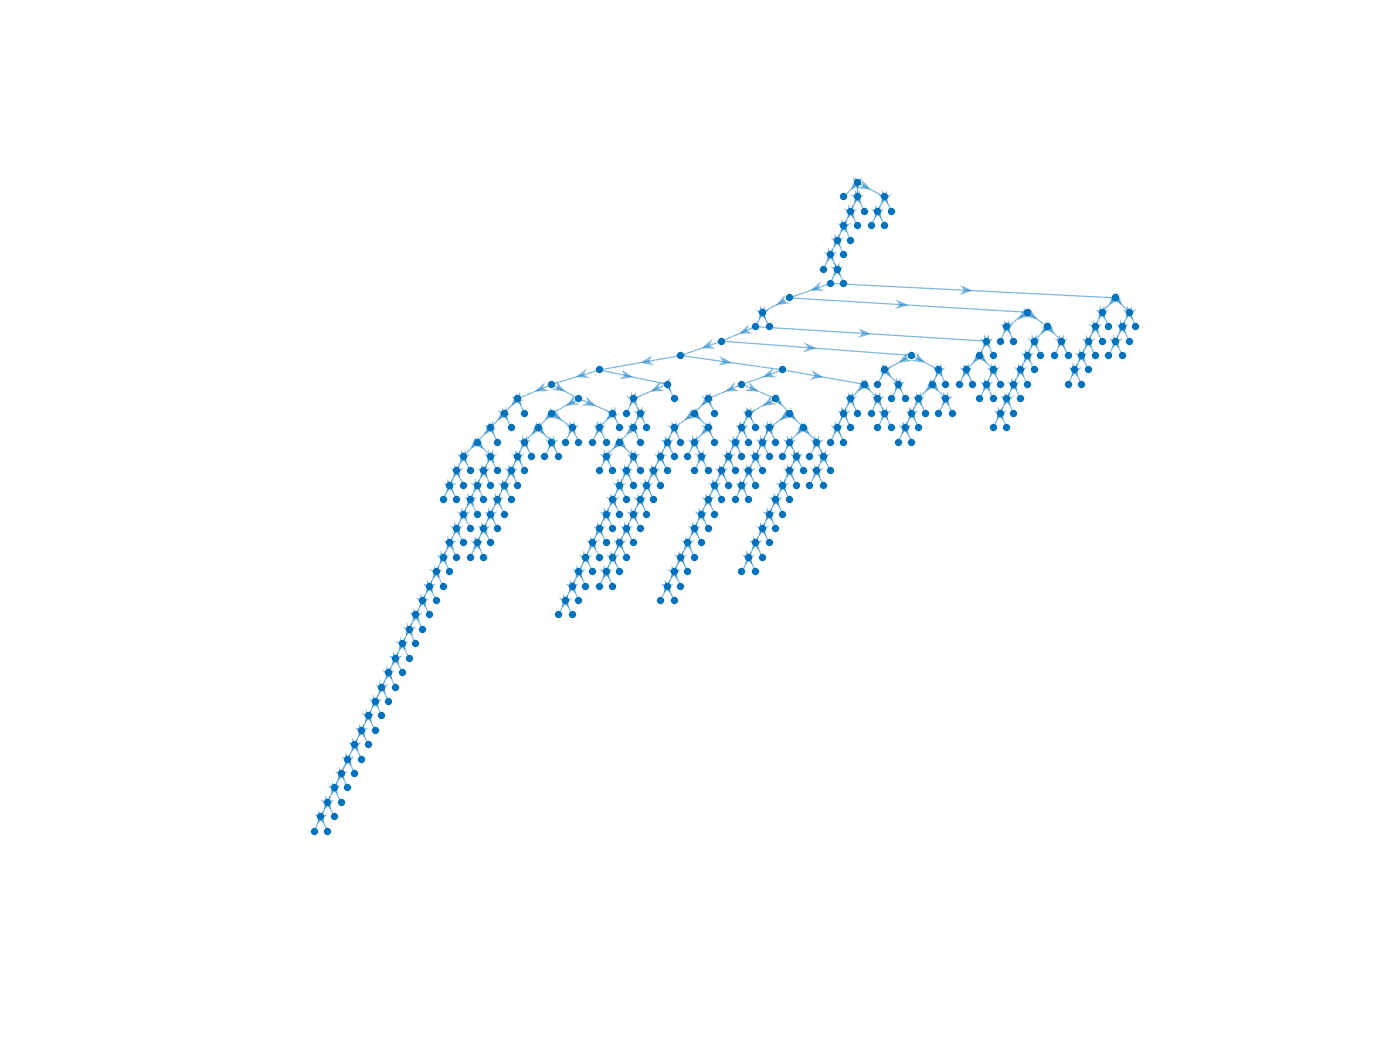

figure('Color','w');
plot(G,'Layout','layered','NodeLabel',{});
axis off

## PROJECT 7: Topological Embedding of Graphs and Covaraince Structures

% Goal:
% The default graph plot suggests that the tree splits into three major
% branches, but the nodes are highly clustered, making the overall
% structure difficult to interpret. A hierarchical (layered) layout
% preserves the ancestral ordering of nodes, but does not provide clear
% geometric separation among the three branches.
%
% This project explores and compares alternative network and graph
% embedding methods to better reveal large-scale structure while
% respecting the underlying graph topology, and to quantify the performance
% of each embedding.
%
% Description:
% In this project, a graph is treated as a simplicial complex. Students will
% develop a topological embedding strategy that incorporate Hodge Laplacians 
% in a principled way to capture higher-order structural information beyond 
% pairwise adjacency. Although the project is motivated by a tree-based example, 
% the proposed methods are applicable to broad classes of graph-structured data,
% including dense graphs derived from correlation or covariance matrices.
%
% While embedding is primarily used for visualization, the resulting
% geometric representations can be further exploited to formulate and
% develop statistical inference procedures on graph-structured data.
% To this end, students will design and implement resampling or
% perturbation strategies to assess the stability and robustness of the
% proposed embeddings, and demonstrate that the embeddings remain
% consistent under controlled resampling and structural perturbations.
%
% Learning outcomes:
% Upon completion of this project, students will be able to (i) formulate
% graphs and networks as simplicial complexes and construct the associated
% boundary operators and Hodge Laplacians; (ii) explain the theoretical
% relationship between graph topology, higher-order structure, and the
% spectral properties of Hodge Laplacians; (iii) design and implement
% topological embedding methods based on node-, edge-, and higher-order
% Laplacians; (iv) quantitatively evaluate and compare the performance of 
% embeddings and stability under resampling.



## PROJECT 8: Hyperbolic Embedding of Graphs and Covariance Structures

% Goal:
% Many graphs, particularly trees and hierarchical networks, exhibit
% exponential growth in the number of nodes as a function of graph depth.
% When embedded in Euclidean space, this growth leads to severe node
% crowding and geometric distortion, obscuring large-scale structure.
%
% Hyperbolic geometry, as realized for example in the Poincaré disk model,
% provides a natural alternative because its exponential volume growth can
% accommodate hierarchical expansion. The goal of this project is to
% investigate whether hyperbolic embeddings provide clearer geometric
% separation and more faithful representations of large-scale structure
% than baseline geometric embeddings, including PCA-based embeddings.
%
% Description:
% In this project, a graph is treated as a simplicial complex, with its
% 1-skeleton serving as the primary object of study. Students will develop
% and implement hyperbolic embedding methods. The embeddings will be 
% formulated using intrinsic graph quantities, including features derived 
% from graph Laplacians or Hodge Laplacians. 
%
% A practical limitation of hyperbolic (and, more generally, geometric)
% embeddings is their sensitivity to data updates: node positions may shift
% substantially when new nodes or edges are introduced. Students will
% investigate strategies to mitigate this instability by fixing or anchoring
% selected nodes of interest, and will analyze how such constraints affect
% embedding stability and geometric distortion.
%
% Anchoring a small number of nodes of interest induces local stability in
% the embedding around the anchored regions, enabling consistent geometric
% reference frames. This stabilization allows statistical analyses to be
% carried out on the embedded coordinates, such as uncertainty quantification,
% hypothesis testing, or resampling-based inference. Students will design
% and implement statistical analysis strategies that leverage anchored
% embeddings to assess robustness and variability in graph-structured or
% covariance data.


% Learning outcomes:
% Upon completion of this project, students will be able to (i) explain the
% mathematical motivation for hyperbolic geometry in representing graphs
% with hierarchical or exponential growth, (ii) implement hyperbolic
% embedding methods and compare them with Euclidean and spectral approaches,
% (iii) quantify embedding quality, and (iv) assess the impact of anchoring 
% or constraints on the robustness of geometric embeddings for graph-structured data.
